## Parametrización de la Ruta

clear all
%Se define el parámetro l como el 40% del alcance horizontal
horizontal_reach=1.225;
l=0.4*horizontal_reach

l = 0.4900

l=0.48;
%Se parametriza la figura
r=0.3*l;
n=15;

tramo1=[linspace(0,l-r,n)' zeros(n,2)];

theta=linspace(-pi/2,pi/2,n);
cx=(l-r);cy=r;cz=0;
tramo2=[cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];

tramo3=[tramo2(end,:);linspace(l-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];

tramo4=[tramo3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

path=[tramo1;tramo2;tramo3;tramo4];

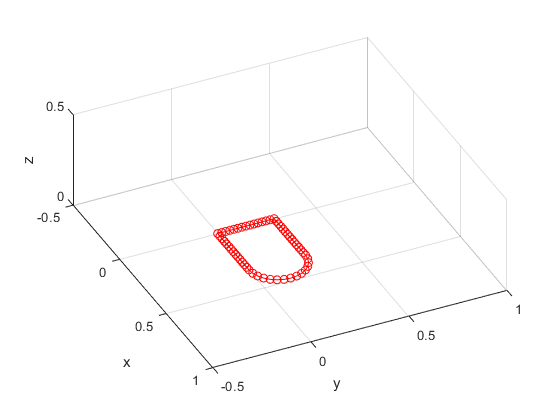

%Comprobamos que la figura esté bien parametrizada en el plano xy
plot3(path(:,1),path(:,2),path(:,3),'-ro')
grid on
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
xlim([-0.500 1.000])
ylim([-0.500 1.000])
zlim([0.000 0.500])
view([64.545 33.537])

clf
%Establecemos ahora la transformación:
R0_t=rotx(45,'deg')

R0_t =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


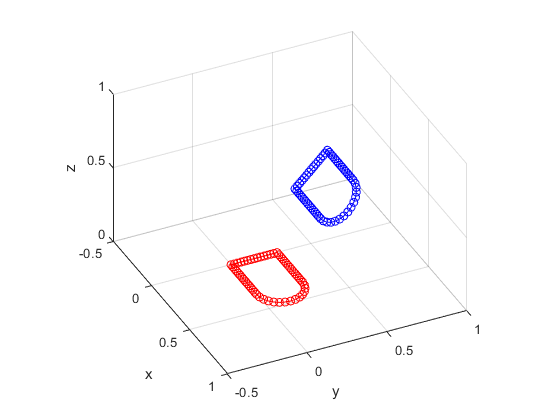

P0_t=[0 0.4 0.4];
%Multiplicamos para hallar la figura en el plano de trabajo
path_=0.*path;
for i=1:length(path(:,1))
    path_(i,:)=R0_t*path(i,:)'+P0_t';
end
plot3(path(:,1),path(:,2),path(:,3),'-ro')
hold on
plot3(path_(:,1),path_(:,2),path_(:,3),'-bo')
grid on
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
xlim([-0.500 1.000])
ylim([-0.500 1.000])
zlim([0.000  1.00])
view([64.545 33.537])
hold off

%Carga del robot desde el toolbox RST
robot=loadrobot("abbIrb1600","DataFormat","row");

ik=inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = homeConfiguration(robot);
robot.BodyNames

ans = 1×7 cell array
    {'link_1'}    {'link_2'}    {'link_3'}    {'link_4'}    {'link_5'}    {'link_6'}    {'tool0'}


## Cinemática Inversa para los puntos de la trayectoria

%El número de waypoints es la longitud de la ruta:
waypoints=length(path(:,1));
%se define un vector de configuraciones
path_configurations=zeros(waypoints,6);
for i=1:waypoints
    tic
    if i>1
        initialguess=path_configurations(i-1,:);
    end
    P0_t=path_(i,:);
    R0_t=rotx(-135,'deg');
    MTHpose = [R0_t P0_t'; 0 0 0 1];
    [configSoln,solnInfo] = ik('tool0',MTHpose,weights,initialguess);
    path_configurations(i,:)=configSoln';
    disp(strcat(num2str(i),"/",num2str(waypoints)))
    toc
end

1/62


Elapsed time is 0.219958 seconds.


2/62


Elapsed time is 0.028537 seconds.


3/62


Elapsed time is 0.030879 seconds.


4/62


Elapsed time is 0.023223 seconds.


5/62


Elapsed time is 0.032717 seconds.


6/62


Elapsed time is 0.019106 seconds.


7/62


Elapsed time is 0.016549 seconds.


8/62


Elapsed time is 0.021098 seconds.


9/62


Elapsed time is 0.021546 seconds.


10/62


Elapsed time is 0.024750 seconds.


11/62


Elapsed time is 0.018655 seconds.


12/62


Elapsed time is 0.018846 seconds.


13/62


Elapsed time is 0.015662 seconds.


14/62


Elapsed time is 0.013977 seconds.


15/62


Elapsed time is 0.013938 seconds.


16/62


Elapsed time is 0.002229 seconds.


17/62


Elapsed time is 0.014497 seconds.


18/62


Elapsed time is 0.018054 seconds.


19/62


Elapsed time is 0.017449 seconds.


20/62


Elapsed time is 0.017461 seconds.


21/62


Elapsed time is 0.016505 seconds.


22/62


Elapsed time is 0.014973 seconds.


23/62


Elapsed time is 0.013401 seconds.


24/62


Elapsed time is 0.015501 seconds.


25/62


Elapsed time is 0.013613 seconds.


26/62


Elapsed time is 0.012009 seconds.


27/62


Elapsed time is 0.014034 seconds.


28/62


Elapsed time is 0.016264 seconds.


29/62


Elapsed time is 0.016880 seconds.


30/62


Elapsed time is 0.015343 seconds.


31/62


Elapsed time is 0.001438 seconds.


32/62


Elapsed time is 0.001411 seconds.


33/62


Elapsed time is 0.013383 seconds.


34/62


Elapsed time is 0.012426 seconds.


35/62


Elapsed time is 0.012646 seconds.


36/62


Elapsed time is 0.012429 seconds.


37/62


Elapsed time is 0.012920 seconds.


38/62


Elapsed time is 0.012329 seconds.


39/62


Elapsed time is 0.012235 seconds.


40/62


Elapsed time is 0.019781 seconds.


41/62


Elapsed time is 0.018100 seconds.


42/62


Elapsed time is 0.019366 seconds.


43/62


Elapsed time is 0.014222 seconds.


44/62


Elapsed time is 0.016553 seconds.


45/62


Elapsed time is 0.014631 seconds.


46/62


Elapsed time is 0.015329 seconds.


47/62


Elapsed time is 0.001488 seconds.


48/62


Elapsed time is 0.001492 seconds.


49/62


Elapsed time is 0.009523 seconds.


50/62


Elapsed time is 0.009891 seconds.


51/62


Elapsed time is 0.009550 seconds.


52/62


Elapsed time is 0.013461 seconds.


53/62


Elapsed time is 0.012921 seconds.


54/62


Elapsed time is 0.012306 seconds.


55/62


Elapsed time is 0.009263 seconds.


56/62


Elapsed time is 0.009749 seconds.


57/62


Elapsed time is 0.009328 seconds.


58/62


Elapsed time is 0.010498 seconds.


59/62


Elapsed time is 0.009868 seconds.


60/62


Elapsed time is 0.008971 seconds.


61/62


Elapsed time is 0.008573 seconds.


62/62


Elapsed time is 0.008329 seconds.


save("integration.mat");


%Para evitar calcular la cinemática inversa cargue los valores
%precalculados del archivo integration.mat
load("integration.mat");

## Animación

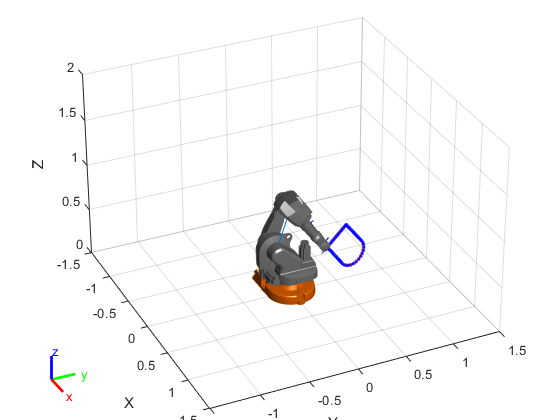

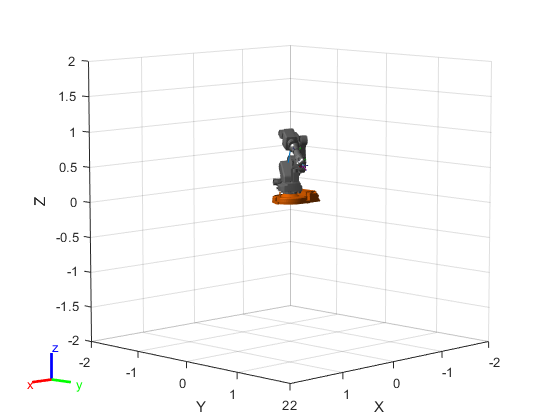

Error using plot3
Invalid handle.

% clf("reset")
% f=figure
%Animación del robot dibujando la trayectoria en el plano de trabajo
fps=20;r=rateControl(fps);
show(robot,path_configurations(1,:));
xlim([-1.5 1.5])
ylim([-1.5 1.5])
zlim([0 2])
view([65,30])
ax=gca;
hold on

repeat=true;
while repeat
    ax=gca;
%     hold on
    plot3(ax,path_(:,1),path_(:,2),path_(:,3),':b.');
    true_path=0.*path_;
    hold on
    for i=1:waypoints
        show(robot,path_configurations(i,:),'PreservePlot',false);
        T0_t=robot.getTransform(path_configurations(i,:),'tool0');
        true_path(i,:)=tform2trvec(T0_t);
        %         hold on
        plot3(ax,true_path(1:i,1),true_path(1:i,2),true_path(1:i,3),'-r');
        
        drawnow
        waitfor(r);
    end
    hold off
end